# Video Pre-Processing & Draw Bounding Box - Test on Full Video

**Aim: **Build on from "Video Pre-Processing Workflow - Test Concept" ***(file:*** ***preprocessing_workflow.mlx)****. *Will now attempt to run code on a full video.

**Summary**: Starting with a video (.avi), individual frames are extracted and stored in a temporary folder. Then, loop through each individual frame for image processing and bounding boxes are overlaid onto orginal image frame. The overlaid images will be saved to the same temporary folder and replace the original image frames. 

**User notes: **

This script is based on the video: **SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi** , 

If you would like to run the script, please ensure the video is in the same directory as this script. Link to the video file can be found on github. 

**Log:** 

**12-Jan-2020; SWC**. Completed code - looping operation worked! Computational time seems reasonable. Next steps: to remove i) bounding boxes outside main channel and ii) small noise objects picked up in some frames (maybe try 'remove if area < x). Check when will drops be classified as doublet! crop bounding boxes and save as individual images.

clear all 
close all 
clc 

##  1) Load Video

vid = VideoReader('SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi'); %read video
totframes = vid.NumFrames %check total num of frames in video

totframes = 1434

## 2) Background Generation - Use Median of Frames

n = 200;    % number of frames to use for background generation 
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end

tic
med_pix = median(frameMat,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 3.103848 seconds.


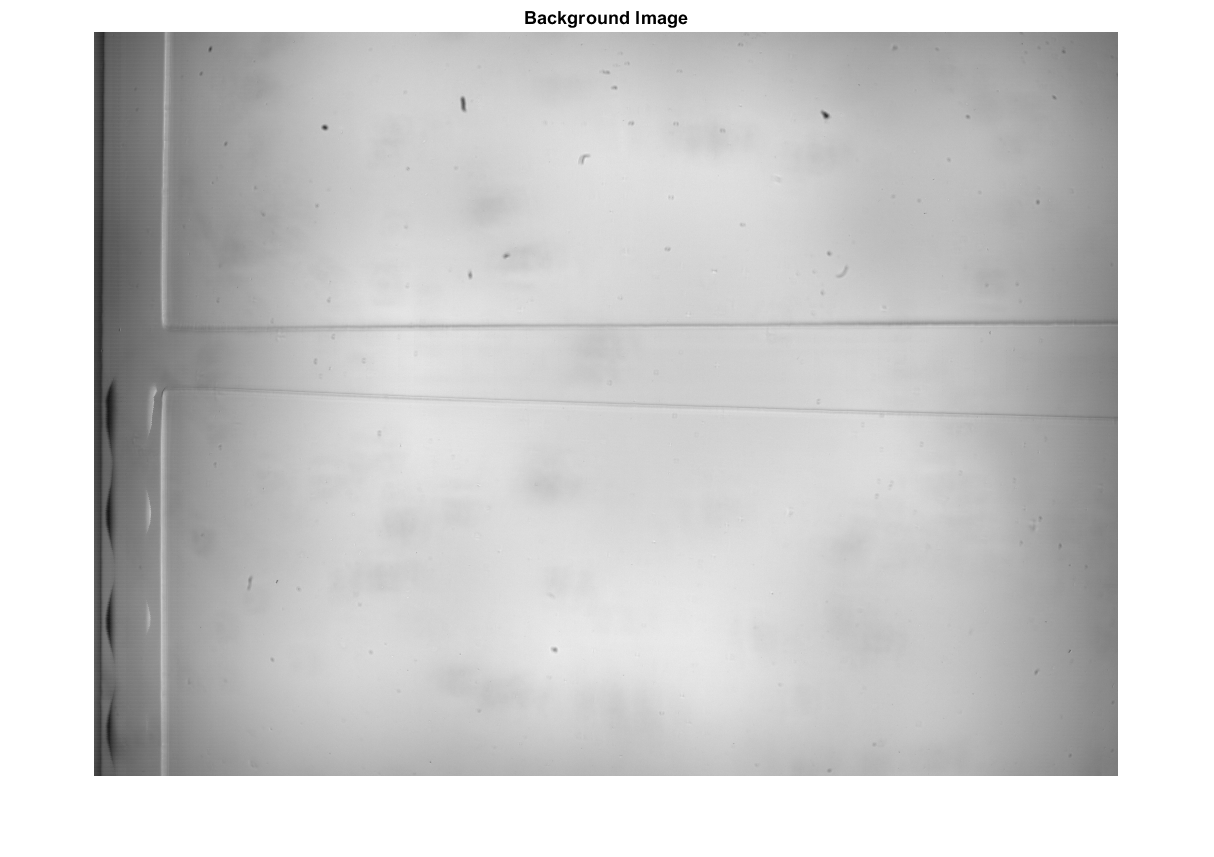


%show generated background 
imshow(med_pix); title("Background Image")

## 3) Extract Video Frames & Save in Temporary Folder 

**Accompanying function file: ***extractVidFrames.m*

*Note: if want to test code, check if the temporary subfolder already exists from previous runs. If so, delete subfolder from the shared drive first before running code.*

- Create temporary folder to store files

mkdir test_0016 % have created 'test_0016' subfolder as example
addpath test_0016 % enable access to subfolder

- Define user inputs for function

vid_file_name = 'SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi'; 
num_frames = 10; % number of frames to extract from video
file_path = 'C:\Users\chong\MATLAB Drive\MEng Research Project 2021 - Machine Learning\1. Preprocessing\test_0016\'; %folder to save images in

- call function

extractVidFrames(vid_file_name, num_frames, file_path); %extracted video frames saved in temporary subfolder

## 4) Create Labelled Video Frames & Save in Temporary Folder 

**Accompanying function file**: *vidFramePreprocess.m*

*Note: original video frame images will be overwritten and replaced with 'labelled' frame images.*

*Labelled as in draw bounding boxes *

temp_folder = dir('test_0016\*.jpg'); 

% cd test_0016\ %set directory to temporary folder

%loop through each frame in subfolder
for i = 1:numel(temp_folder)
    file = temp_folder(i).name;
    bg = med_pix; %background image - generated earlier
    t = 0.2; %treshold value
    foldername = 'test_0016';
    vidFramePreprocess(file, bg, t, foldername);
end


Once loop operation finished, check temporary subfolder => should be able to see video frames with bounded drops. 